## Add stuff to path

if(ispc)
    homeFolder = 'C:\Users\rhc307\';
else
    homeFolder = '/home/raeed/';
end
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'BumpCurl' filesep 'lib' filesep])
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'lib']))
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'BumpCurl' filesep 'Han' filesep '20170127' filesep])

clear homeFolder


## Load in CDS files and save

lab=6;
ranBy='ranByRaeed';
monkey='monkeyHan';
task='taskCObump';
array='arrayLeftS1Area2';
folder='C:\Users\Raeed\Projects\limblab\data-raeed\BumpCurl\Han\20170127\preCDS';
base_fname='Han_20170127_CObumpcurl_baseline_area2EMG_001';
adapt_fname='Han_20170127_CObumpcurl_adaptation_area2EMG_002';
wash_fname='Han_20170127_CObumpcurl_washout_area2EMG_003';
mapfile='mapFileC:\Users\rhc307\Projects\limblab\data-raeed\ForceKin\OutOutReach\Han\mapfile\left_S1\SN 6251-001459.cmp';

% Make CDS file
base_cds = commonDataStructure();
base_cds.file2cds([folder filesep base_fname],ranBy,array,monkey,lab,'ignoreJumps',task,mapfile);
adapt_cds = commonDataStructure();
adapt_cds.file2cds([folder filesep adapt_fname],ranBy,array,monkey,lab,'ignoreJumps',task,mapfile);
wash_cds = commonDataStructure();
wash_cds.file2cds([folder filesep wash_fname],ranBy,array,monkey,lab,'ignoreJumps',task,mapfile);

save([folder '\..\CDS\bumpcurl.mat'],'base_cds','adapt_cds','wash_cds');


## Check trial tables

% check reward tables
base_table = base_cds.trials(base_cds.trials.result=='R',:);
adapt_table = adapt_cds.trials(adapt_cds.trials.result=='R',:);
wash_table = wash_cds.trials(wash_cds.trials.result=='R',:);

% clear all trials with no center hold bump
base_table = base_table(base_table.ctrHoldBump==1,:);
adapt_table = adapt_table(adapt_table.ctrHoldBump==1,:);
wash_table = wash_table(wash_table.ctrHoldBump==1,:);


## Move CDS into Experiment class

% DL stuff
base_ex = experiment();
% set variables to load from cds
base_ex.meta.hasLfp=false;
base_ex.meta.hasKinematics=true;
base_ex.meta.hasForce=true;
base_ex.meta.hasUnits=true;
base_ex.meta.hasTrials=true;
base_ex.meta.hasAnalog=true;
% add session to experiment
base_ex.addSession(base_cds);
% Bin experiment data
base_ex.binConfig.include(1).field='units';
base_ex.binConfig.include(1).which=find([base_ex.units.data.ID]==0);
base_ex.binConfig.include(2).field='kin';
base_ex.binConfig.include(2).which={};
base_ex.binConfig.include(3).field='force';
base_ex.binConfig.include(3).which={};
% base_ex.binConfig.include(3).field='analog';
% base_ex.binConfig.include(3).which=base_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
base_ex.firingRateConfig.cropType='tightCrop';
base_ex.firingRateConfig.offset=-0.015;

base_ex.binData()

base_data = base_ex.bin.data;

% adapt data
adapt_ex = experiment();
adapt_ex.meta.hasLfp=false;
adapt_ex.meta.hasKinematics=true;
adapt_ex.meta.hasForce=true;
adapt_ex.meta.hasUnits=true;
adapt_ex.meta.hasTrials=true;
adapt_ex.meta.hasAnalog=true;
% add session to experiment
adapt_ex.addSession(adapt_cds);
% Bin experiment data
adapt_ex.binConfig.include(1).field='units';
adapt_ex.binConfig.include(1).which=find([adapt_ex.units.data.ID]==0);
adapt_ex.binConfig.include(2).field='kin';
adapt_ex.binConfig.include(2).which={};
adapt_ex.binConfig.include(3).field='force';
adapt_ex.binConfig.include(3).which={};
% base_ex.binConfig.include(3).field='analog';
% base_ex.binConfig.include(3).which=base_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
adapt_ex.firingRateConfig.cropType='tightCrop';
adapt_ex.firingRateConfig.offset=-0.015;

adapt_ex.binData()

adapt_data = adapt_ex.bin.data;

% wash data
wash_ex = experiment();
% set variables to load from cds
wash_ex.meta.hasLfp=false;
wash_ex.meta.hasKinematics=true;
wash_ex.meta.hasForce=true;
wash_ex.meta.hasUnits=true;
wash_ex.meta.hasTrials=true;
wash_ex.meta.hasAnalog=true;
% add session to experiment
wash_ex.addSession(wash_cds);
% Bin experiment data
wash_ex.binConfig.include(1).field='units';
wash_ex.binConfig.include(1).which=find([wash_ex.units.data.ID]==0);
wash_ex.binConfig.include(2).field='kin';
wash_ex.binConfig.include(2).which={};
wash_ex.binConfig.include(3).field='force';
wash_ex.binConfig.include(3).which={};
% base_ex.binConfig.include(3).field='analog';
% base_ex.binConfig.include(3).which=base_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
wash_ex.firingRateConfig.cropType='tightCrop';
wash_ex.firingRateConfig.offset=-0.015;

wash_ex.binData()

wash_data = wash_ex.bin.data;


## Correct bump directions in trial tables

if(~exist('bump_shifted'))
    base_table.bumpDir = mod(base_table.bumpDir + base_table.tgtDir,360);
    adapt_table.bumpDir = mod(adapt_table.bumpDir + adapt_table.tgtDir,360);
    wash_table.bumpDir = mod(wash_table.bumpDir + wash_table.tgtDir,360);
    bump_shifted = true;
end


## Try PCA on data

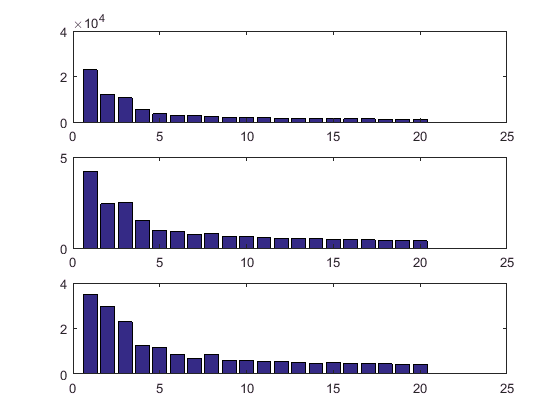

neurIDX = contains(base_data.Properties.VariableNames,'LeftS1Area2CH');
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

[coeff,scores,latent_eigs] = pca([base_bumps;adapt_bumps;wash_bumps]);
% [base_coeff,base_scores,base_scree] = pca([base_bumps]);

% project adapt and wash bumps into pc space
% center
% adapt_bumps_ctr = adapt_bumps - mean(adapt_bumps);
% wash_bumps_ctr = wash_bumps - mean(wash_bumps);
% 
% % project
% adapt_scores = adapt_bumps_ctr*base_coeff;
% wash_scores = wash_bumps_ctr*base_coeff;
% 


base_idx = (1:size(base_bumps,1))';
adapt_idx = (base_idx(end)+1:base_idx(end)+size(adapt_bumps,1))';
wash_idx = (adapt_idx(end)+1:adapt_idx(end)+size(wash_bumps,1))';

base_scores = scores(base_idx,:);
adapt_scores = scores(adapt_idx,:);
wash_scores = scores(wash_idx,:);

adapt_scree = var(adapt_scores);
wash_scree = var(wash_scores);

figure
subplot(311)
bar(base_scree(1:20))
subplot(312)
bar(adapt_scree(1:20))
subplot(313)
bar(wash_scree(1:20))

## Look at PCs time traces

## Plot color bumps

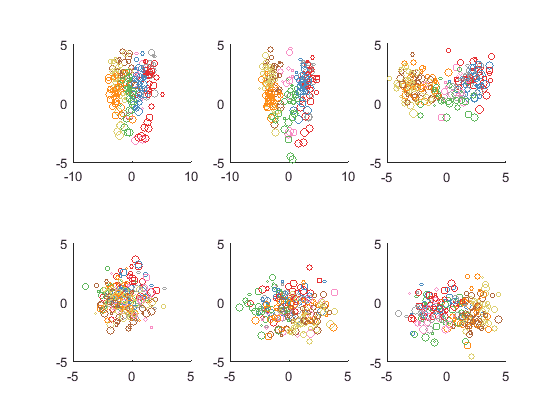

colors = linspecer(8);
base_colors = colors(base_table.bumpDir/45+1,:);
adapt_colors = colors(adapt_table.bumpDir/45+1,:);
wash_colors = colors(wash_table.bumpDir/45+1,:);

figure
S = linspace(1,200,size(base_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(base_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),'Color',base_colors(i,:))
%         plot(base_scores(idx,1),base_scores(idx,2),'o','Color',base_colors(i,:))
        hold on
        scatter3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),S(i),base_colors(i,:))
    end
    grid off
    axis square
end

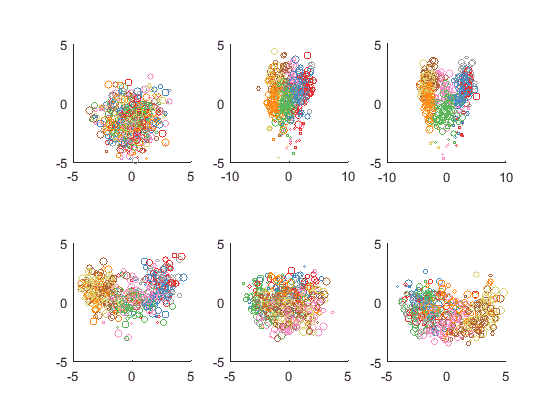



figure
S = linspace(1,200,size(adapt_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(adapt_colors,1)
        
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),'Color',adapt_colors(i,:))
%         plot(adapt_scores(idx,1),adapt_scores(idx,2),'o','Color',adapt_colors(i,:))
        hold on
%         scatter(adapt_scores(idx,1),adapt_scores(idx,2),S(i),adapt_colors(i,:))
        scatter3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),S(i),adapt_colors(i,:))
        
    end
    grid off
    axis square
end

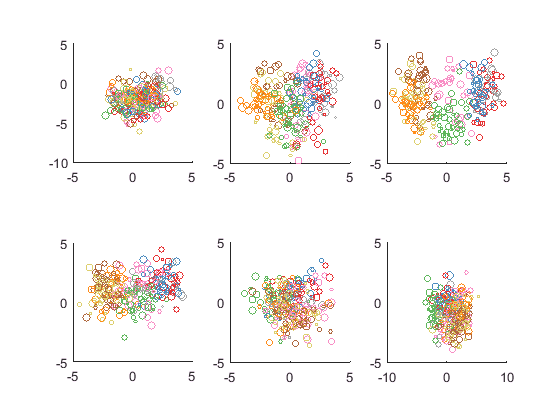


figure
S = linspace(1,200,size(wash_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(wash_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),'Color',wash_colors(i,:))
%         plot(wash_scores(idx,1),wash_scores(idx,2),'o','Color',wash_colors(i,:))
        hold on
%         scatter(wash_scores(idx,1),wash_scores(idx,2),S(i),wash_colors(i,:))
        scatter3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),S(i),wash_colors(i,:))
    end
    grid off
    axis square
end

## Try time spread PCA

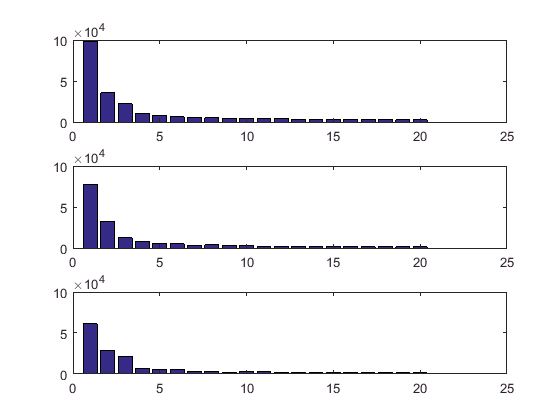

neurIDX = contains(base_data.Properties.VariableNames,'LeftS1Area2CH');
% base_bumps = [];
% for trialCtr=1:height(base_table)
%     base_bumps = [base_bumps; reshape(base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% end
% 
% neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
% adapt_bumps = [];
% for trialCtr=1:height(adapt_table)
%     adapt_bumps = [adapt_bumps; reshape(adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% end
% 
% neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
% wash_bumps = [];
% for trialCtr=1:height(wash_table)
%     wash_bumps = [wash_bumps; reshape(wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% end

% Try picking out the time points
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; reshape(base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.15,neurIDX},1,3*sum(neurIDX))];
end

neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; reshape(adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr)+0.05 & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.20,neurIDX},1,3*sum(neurIDX))];
end

neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; reshape(wash_data{wash_data.t>=wash_table.bumpTime(trialCtr)+0.05 & wash_data.t<=wash_table.bumpTime(trialCtr)+0.20,neurIDX},1,3*sum(neurIDX))];
end

% [coeff,scores,latent_eigs] = pca([base_bumps;adapt_bumps;wash_bumps]);
[base_coeff,base_scores,base_scree] = pca(base_bumps);
% [~,adapt_scores,~] = pca(adapt_bumps);
% [~,wash_scores,~] = pca(wash_bumps);
% 
% project adapt and wash bumps into pc space
% center
adapt_bumps_ctr = adapt_bumps - mean(adapt_bumps);
wash_bumps_ctr = wash_bumps - mean(wash_bumps);

% project
adapt_scores = adapt_bumps_ctr*base_coeff;
wash_scores = wash_bumps_ctr*base_coeff;

adapt_scree = var(adapt_scores);
wash_scree = var(wash_scores);

% base_idx = (1:size(base_bumps,1))';
% adapt_idx = (base_idx(end)+1:base_idx(end)+size(adapt_bumps,1))';
% wash_idx = (adapt_idx(end)+1:adapt_idx(end)+size(wash_bumps,1))';
% 
% base_scores = scores(base_idx,:);
% adapt_scores = scores(adapt_idx,:);
% wash_scores = scores(wash_idx,:);

figure
subplot(311)
bar(base_scree(1:20))
subplot(312)
bar(adapt_scree(1:20))
subplot(313)
bar(wash_scree(1:20))

## plot colors

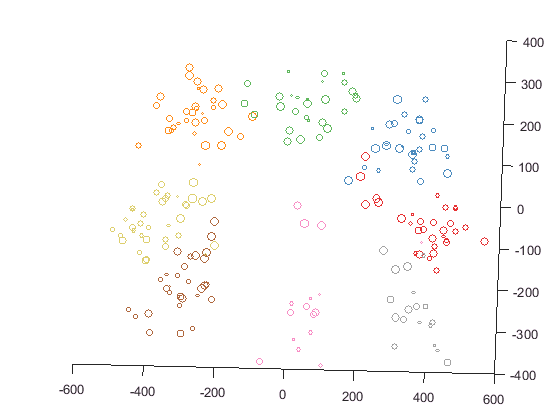

colors = linspecer(8);
base_colors = colors(base_table.bumpDir/45+1,:);
adapt_colors = colors(adapt_table.bumpDir/45+1,:);
wash_colors = colors(wash_table.bumpDir/45+1,:);
figure
S = linspace(1,40,size(base_scores,1));
scatter3(base_scores(:,1),base_scores(:,2),base_scores(:,3),S,base_colors)
% scatter(base_scores(:,1),base_scores(:,2),S,base_colors)
grid off

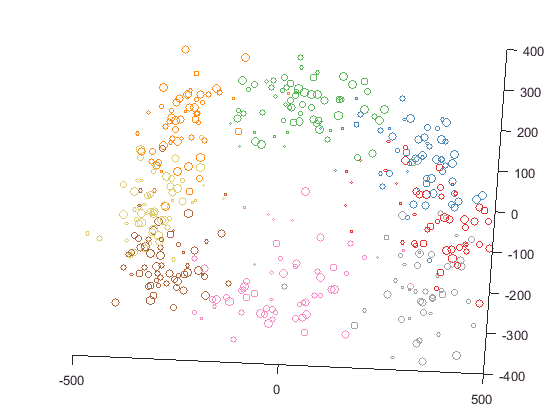

% axis equal
figure
S = linspace(1,40,size(adapt_scores,1));
scatter3(adapt_scores(:,1),adapt_scores(:,2),adapt_scores(:,3),S,adapt_colors)
% scatter(adapt_scores(:,1),adapt_scores(:,2),S,adapt_colors)
grid off

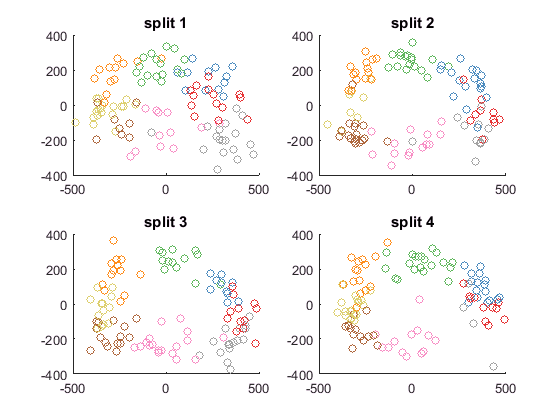

% axis equal
figure
subplot(221)
scatter(adapt_scores(1:111,1),adapt_scores(1:111,2),30,adapt_colors(1:111,:))
title 'split 1'
subplot(222)
scatter(adapt_scores(112:222,1),adapt_scores(112:222,2),30,adapt_colors(112:222,:))
title 'split 2'
subplot(223)
scatter(adapt_scores(223:333,1),adapt_scores(223:333,2),30,adapt_colors(223:333,:))
title 'split 3'
subplot(224)
scatter(adapt_scores(334:444,1),adapt_scores(334:444,2),30,adapt_colors(334:444,:))
title 'split 4'

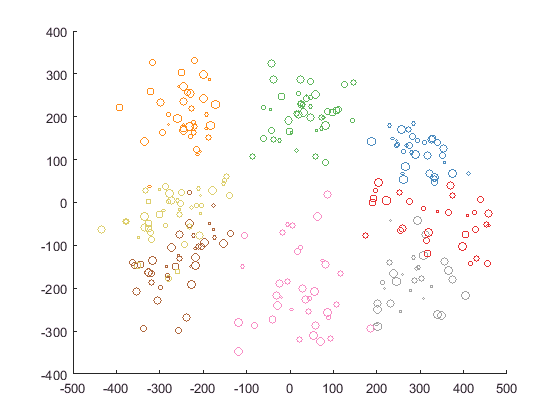


figure
S = linspace(1,40,size(wash_scores,1));
scatter3(wash_scores(:,1),wash_scores(:,2),wash_scores(:,3),S,wash_colors)
% scatter(wash_scores(:,1),wash_scores(:,2),S,wash_colors)
grid off

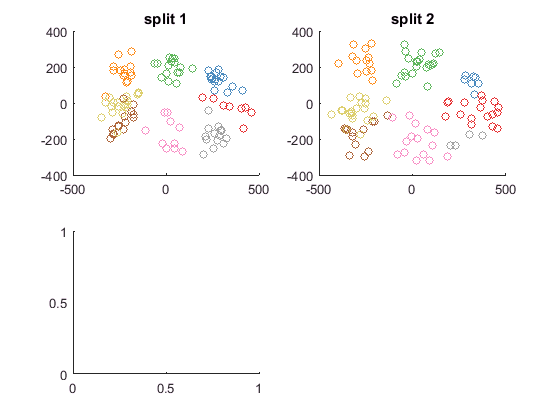

% axis equal

figure
subplot(221)
scatter(wash_scores(1:111,1),wash_scores(1:111,2),30,wash_colors(1:111,:))
title 'split 1'
subplot(222)
scatter(wash_scores(112:222,1),wash_scores(112:222,2),30,wash_colors(112:222,:))
title 'split 2'
subplot(223)

scatter(wash_scores(223:333,1),wash_scores(223:333,2),30,wash_colors(223:333,:))

Index exceeds matrix dimensions.

title 'split 3'
subplot(224)
scatter(wash_scores(334:444,1),wash_scores(334:444,2),30,wash_colors(334:444,:))
title 'split 4'



## Try mahalanobis distance on time-spread PCA

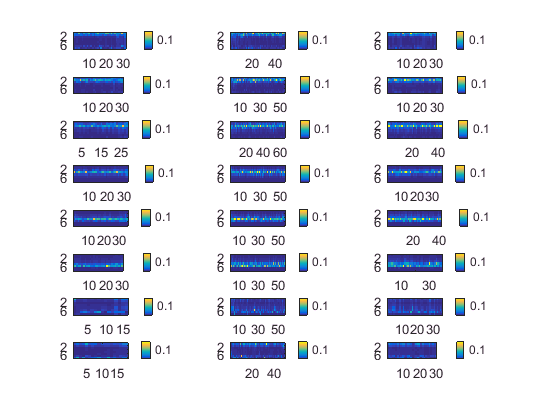

base_clusters = cell(8,1);
for i = 1:8
    base_clusters{i} = base_scores(base_table.bumpDir/45+1==i,1:12);
end

adapt_clusters = cell(8,1);
for i = 1:8
    adapt_clusters{i} = adapt_scores(adapt_table.bumpDir/45+1==i,1:12);
end

wash_clusters = cell(8,1);
for i = 1:8
    wash_clusters{i} = wash_scores(wash_table.bumpDir/45+1==i,1:12);
end

min_mahal = inf;
max_mahal = 0;

base_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(base_clusters{j},1)
        for i = 1:8
            if i==j
                base_mahal{j}(trialCtr,i) = mahal(base_clusters{j}(trialCtr,1:12),base_clusters{i}([1:trialCtr-1 trialCtr+1:end],:));
            else
                base_mahal{j}(trialCtr,i) = mahal(base_clusters{j}(trialCtr,1:12),base_clusters{i});
            end
            if min_mahal>base_mahal{j}(trialCtr,i)
                min_mahal = base_mahal{j}(trialCtr,i);
            end
            if max_mahal<base_mahal{j}(trialCtr,i)
                max_mahal = base_mahal{j}(trialCtr,i);
            end
        end
    end
end

adapt_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(adapt_clusters{j},1)
        for i = 1:8
            adapt_mahal{j}(trialCtr,i) = mahal(adapt_clusters{j}(trialCtr,1:12),base_clusters{i});
        end
        if min_mahal>adapt_mahal{j}(trialCtr,i)
            min_mahal = adapt_mahal{j}(trialCtr,i);
        end
        if max_mahal<adapt_mahal{j}(trialCtr,i)
            max_mahal = adapt_mahal{j}(trialCtr,i);
        end
    end
end
wash_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(wash_clusters{j},1)
        for i = 1:8
            wash_mahal{j}(trialCtr,i) = mahal(wash_clusters{j}(trialCtr,1:12),base_clusters{i});
        end
        if min_mahal>wash_mahal{j}(trialCtr,i)
            min_mahal = wash_mahal{j}(trialCtr,i);
        end
        if max_mahal<wash_mahal{j}(trialCtr,i)
            max_mahal = wash_mahal{j}(trialCtr,i);
        end
    end
end

figure
for i = 1:8
    subplot(8,3,3*(i-1)+1)
    imagesc(1./base_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
    subplot(8,3,3*(i-1)+2)
    imagesc(1./adapt_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
    subplot(8,3,3*(i-1)+3)
    imagesc(1./wash_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
end

## Calculate principle angles

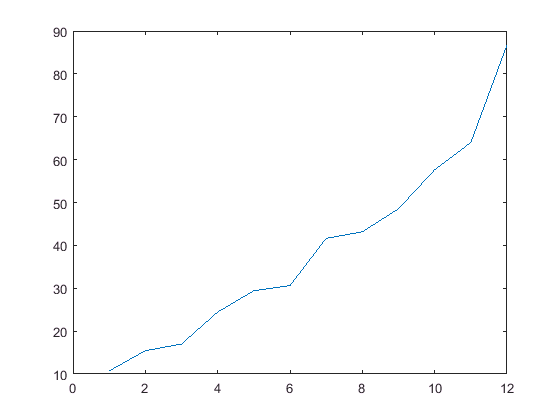

[base_coeff,base_scores,base_scree] = pca(base_bumps);
[adapt_coeff,adapt_scores,~] = pca(adapt_bumps);
[wash_coeff,wash_scores,~] = pca(wash_bumps);

adapt_base_angles = principle_angles(base_coeff(:,1:12),wash_coeff(:,1:12));

figure
plot(adapt_base_angles*180/pi)

## Look at behavior

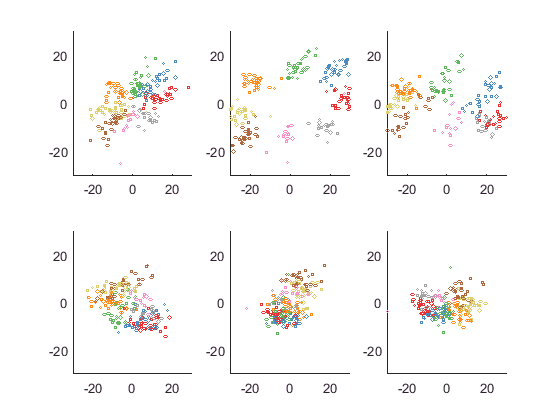

% kinIDX = [4 5];
kinIDX = [6 7];
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

colors = linspecer(8);
base_colors = colors(base_table.bumpDir/45+1,:);
adapt_colors = colors(adapt_table.bumpDir/45+1,:);
wash_colors = colors(wash_table.bumpDir/45+1,:);

figure
S = linspace(1,40,size(base_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(base_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),'Color',base_colors(i,:))
%         plot(base_scores(idx,1),base_scores(idx,2),'o','Color',base_colors(i,:))
        hold on
        scatter(base_bumps(idx,1),base_bumps(idx,2),S(i),base_colors(i,:))
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end

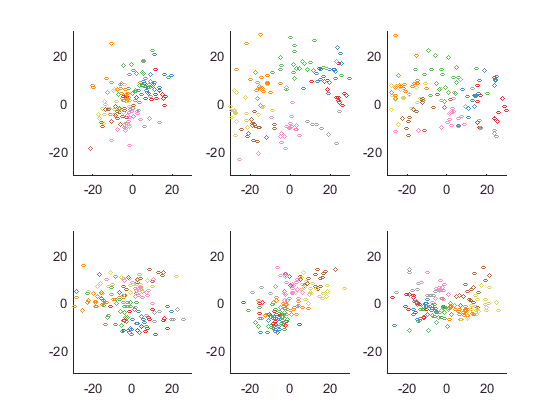



figure
S = linspace(1,40,size(adapt_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = size(adapt_colors,1)-150:size(adapt_colors,1)
        
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),'Color',adapt_colors(i,:))
%         plot(adapt_scores(idx,1),adapt_scores(idx,2),'o','Color',adapt_colors(i,:))
        hold on
        scatter(adapt_bumps(idx,1),adapt_bumps(idx,2),S(i),adapt_colors(i,:))
%         scatter3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),S(i),adapt_colors(i,:))
        
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end

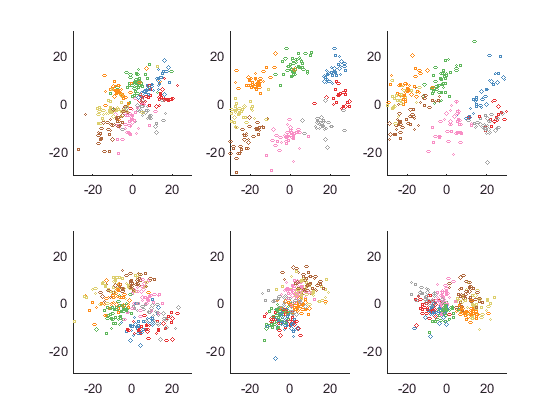


figure
S = linspace(1,40,size(wash_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(wash_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),'Color',wash_colors(i,:))
%         plot(wash_scores(idx,1),wash_scores(idx,2),'o','Color',wash_colors(i,:))
        hold on
        scatter(wash_bumps(idx,1),wash_bumps(idx,2),S(i),wash_colors(i,:))
        
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end